# Testing program

for 'rounded_step_gen' function.

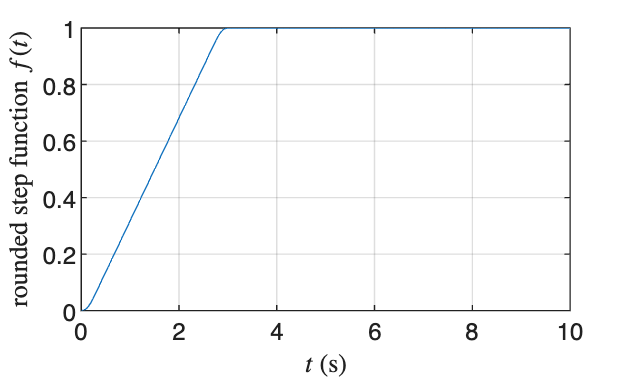

clearvars, clc
tt  = linspace(0,10,800);

st0  = 0.0;
t1   = 0.25;
t3   = 3;

stepp = [st0,t1,t3];

lt = length(tt);

fa   = zeros(lt,1);
dfa  = fa;
ddfa = fa;

for ii = 1:lt
    t = tt(ii);
    [fa(ii),dfa(ii),ddfa(ii)] = rounded_step_gen(t,stepp);
end

figure(1)
plot(tt,fa)
xlabel('$t$ (s)','interpreter','latex')
ylabel('rounded step function $f(t)$','interpreter','latex')
grid on

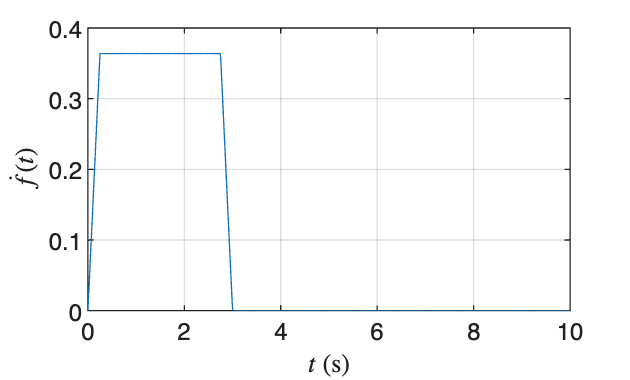


figure(2)
plot(tt,dfa)
xlabel('$t$ (s)','interpreter','latex')
ylabel('$\dot{f}(t)$','interpreter','latex')
grid on

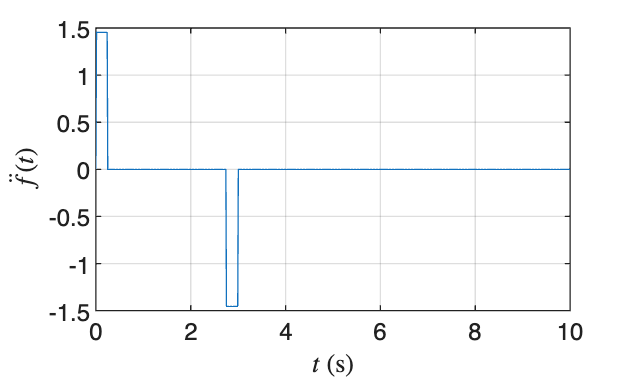


figure(3)
plot(tt,ddfa)
xlabel('$t$ (s)','interpreter','latex')
ylabel('$\ddot{f}(t)$','interpreter','latex')
grid on